# **Scripts for Morse Code Checking**

## **Generating Morse Code from Text**

fs=8000;
[s,y]=morse_encode('plasmonic CDI',fs);

%plotting the encoded signal
data=y;
t=(0:length(data)-1)/fs;
plot(t,data)
xlabel('Time (seconds)')
ylabel('Amplitude')

## Decoding Morse Code to Normal Text

decoded=morse_decode(s)

decoded = 'PLASMONIC CDI'

## Decoded directly from Morse audio using the function defined at end

morse=decode_morse_audio('test.wav')

morse = '.--. .-.. .- ... -- --- -. .. -.-.   -.-. -.. ..'

%checking with the morse to text function
morse_decode(morse)

ans = 'PLASMONIC CDI'

## Analysing the Sound Signal from Audio of Morse Code

[data,Fs]=audioread("test.wav");

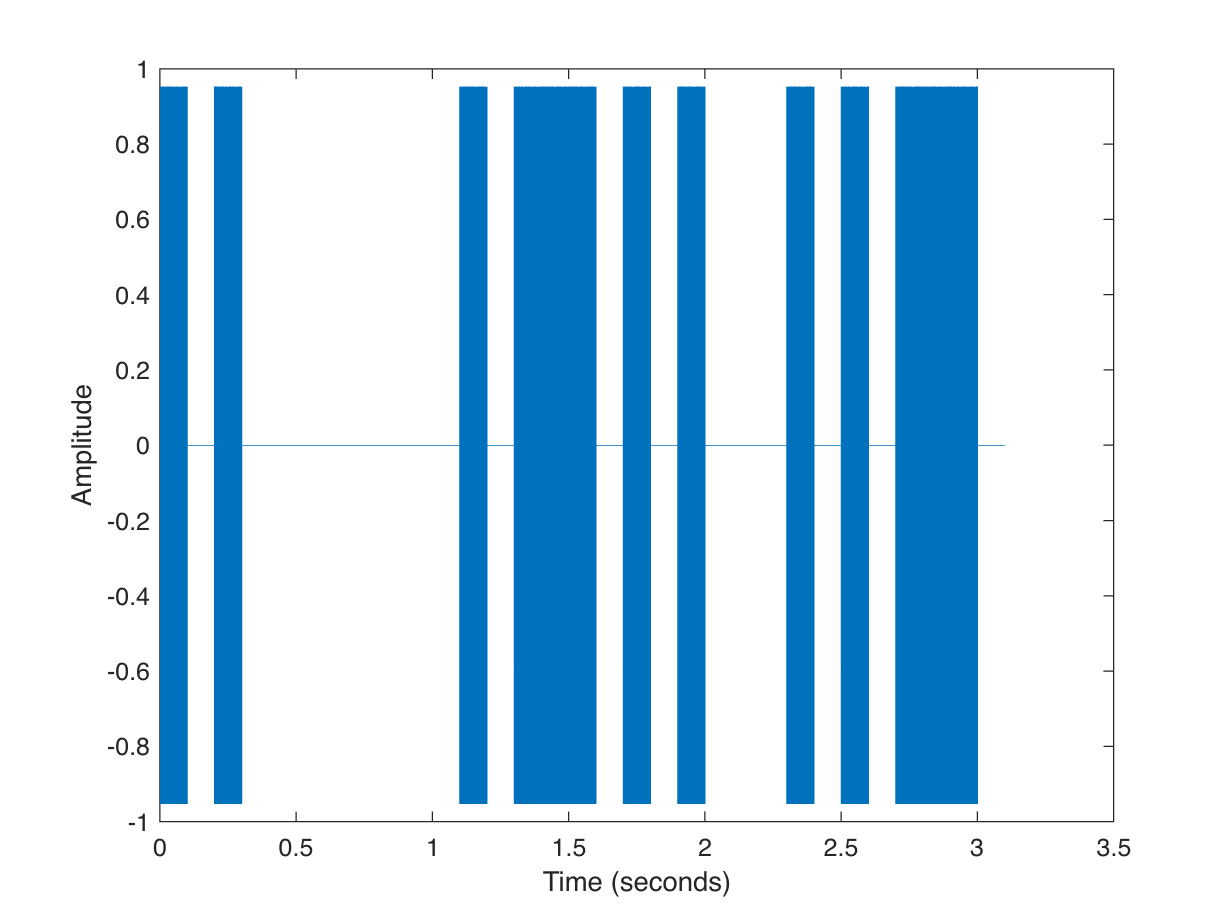

%plotting the input signal
t=(0:length(data)-1)/Fs;
plot(t,data)
xlabel('Time (seconds)')
ylabel('Amplitude')

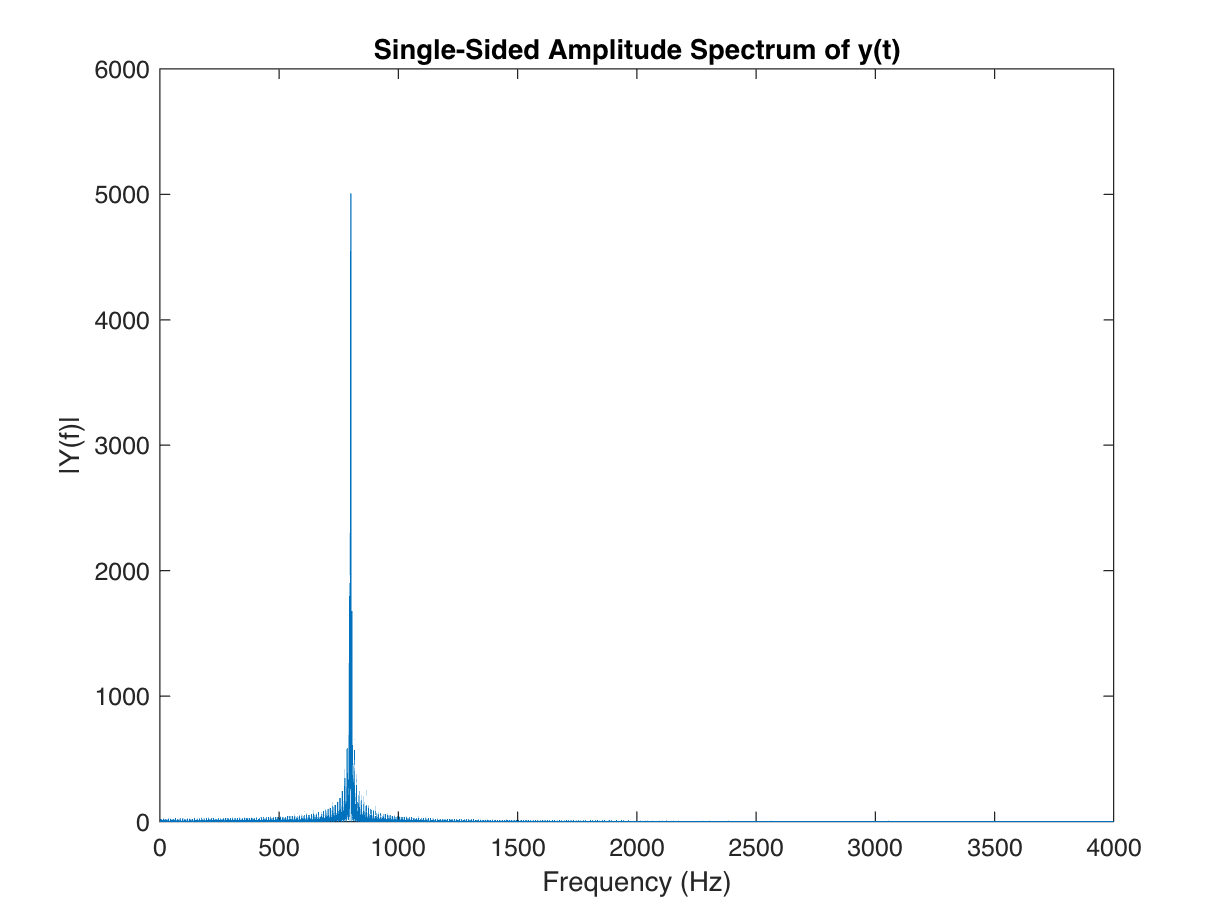

%check fourier Transform of signal
L = length(data);
NFFT = 2^nextpow2(L);
y_fft = abs(fft(data,NFFT));
% creating frequency axis
freq = Fs/2*linspace(0,1,NFFT/2+1);
% Plot single-sided amplitude spectrum.
plot(freq,y_fft(1:NFFT/2+1));
title('Single-Sided Amplitude Spectrum of y(t)');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

### **This section is the step by step explanation of the decode_morse_audio function:**

%segmenting
%output is in segments variable
%each row is a one sound here

segment_duration=0.1; %seconds
len_segment = fix((Fs * segment_duration)); %there was a +1
num_segments = ceil(length(data) / len_segment);
  
% Initializing segments matrix
segments = zeros(num_segments, len_segment);
    
for i = 1:num_segments
   % Determine the start and end indices for the current segment
   start_idx = (i - 1) * len_segment + 1;
   end_idx = min(start_idx + len_segment - 1, length(data));
 
   segment = data(start_idx:end_idx);
        
  if length(segment) < len_segment
      segment = [segment, zeros(1, len_segment - length(segment))]; %zero padding if needed
  end
  
  segments(i, :) = segment;
end

%clearing unncessary varibales
clearvars -except segments fs Fs decoded data

%converting each row to sequence of 1 if there was sound and 0 if no sound
threshold=5 ; %no of non zero elements that can be present in one row to make it still a silence
[row,column]=size(segments);

for i=1:row
    count=0 ; %counting non zero elelemt in one row
    for j=1:column
        if segments(i,j)~=0
            count=count+1;
        end
    end
    if count>threshold
        segments(i,:)=ones(1,column);
    else
        segments(i,:)=zeros(1,column);
    end
end

%transforming the segments matrix into morse code symbols
i = 1;
morse = '';
[row, column] = size(segments);

while i <= row

    % Check for dot condition
    if (i+1 <= row) && (sum(segments(i, :)) > 0) && (sum(segments(i+1, :)) == 0)
        morse = [morse, '.'];
        i = i + 2;
        continue;
    end
    
    % Check for dash condition
    if (i+3 <= row) && (sum(segments(i, :)) > 0) && (sum(segments(i+1, :)) > 0) && (sum(segments(i+2, :)) > 0) && (sum(segments(i+3, :)) == 0)
        morse = [morse, '-'];
        i = i + 4;
        continue;
    end

    % Check for word space (7 consecutive rows of 0s)
    if (i+6 <= row) && all(sum(segments(i:i+6, :)) == 0)
        morse = [morse, '   '];
        i = i + 7;
        continue;
    end

    % Check for letter space (2 consecutive rows of 0s)
    if (i+1 <= row) && all(sum(segments(i:i+1, :)) == 0)
        morse = [morse, ' '];
        i = i + 2;
        continue;
    end

    % If none of the conditions match, just move to the next row
    i = i + 1;
end

disp(morse)

..   .-.. ..-


disp(morse_decode(morse))

I LU


# **Defined Functions**

## Function for Morse Code Encoding

function [s,y]=morse_encode(x,fs)
% y will have audio amplitudes and s will have the morse code.
% fs for sampling frequency
%y_matrix is the matrix form before flatening for sound vector

% table of characters
d = { ...
    ' ',' ';
    'A','.-';
    'B','-...';
    'C','-.-.';
    'D','-..';
    'E','.';
    'F','..-.';
    'G','--.';
    'H','....';
    'I','..';
    'J','.---';
    'K','-.-';
    'L','.-..';
    'M','--';
    'N','-.';
    'O','---';
    'P','.--.';
    'Q','--.-';
    'R','.-.';
    'S','...';
    'T','-';
    'U','..-';
    'V','...-';
    'W','.--';
    'X','-..-';
    'Y','-.--';
    'Z','--..';
    '0','-----';
    '1','.---';
    '2','..---';
    '3','...--';
    '4','....-';
    '5','.....';
    '6','-....';
    '7','--...';
    '8','---..';
    '9','----.';
    '.','.-.-.-';
    ',','--..--';
    '?','..--..';
    '''','.----.';
    '!','-.-.--';
};

% sound constants
tone = 800; % tone frequency (Hz)
unit = 0.1; % unit duration (s)
%fs = 8000; % sampling rate (Hz), must be multiple of tone to avoid gliches

% converts text string in Morse code cell array
[~,kb] = ismember(upper(x(:)),d(:,1)); %finding the row numbers of the matched characters from cell array

% any unknown character replaced by space
kb(kb<1) = 1;

% makes Morse code string
s = strjoin(d(kb,2),' '); %1 extra space is getting added between each morse symbol

    b = strrep(s,'.','10'); % dot is 1 unit length + 1 unit space
    b = strrep(b,'-','1110'); % dash is 3 units length + 1 unit space
    b = strrep(b,'   ','0000000'); % space between words is 7 units
    b = strrep(b,' ','00'); % space beween letters is 3 units (1 already added)
    w = logical(str2num(b(:))');
  
   y = bin2wav(w,fs,tone,unit);


soundsc(y,fs);

%generating file name

rand_number = randi(200); % Change 100 to any desired range
%filename = ['Morse',num2str(rand_number),'.wav'];
%audiowrite(filename, y, fs);
audiowrite('test.wav',y,fs)
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [y] = bin2wav(x,fs,tone,unit)
% makes an audio signal from x

n = round(unit*fs); % number of samples in a unit
m = length(x); % number of units
y = zeros(n,m); % makes a matrix of flat signal
s = linspace(0,2*pi*tone*unit,n+1)'; %generating time vector for one full cycle including 0
y(:,x) = repmat(sin(s(1:end-1)),1,sum(x)); %inserting sound only for 1 and silience for 0. Repeating column wise
%y_matrix=y;
y = y(:); %flattening the sound vector
end


## Function for Morse Code Decoding from symbols

function s=morse_decode(x)
d = { ...
    ' ',' ';
    'A','.-';
    'B','-...';
    'C','-.-.';
    'D','-..';
    'E','.';
    'F','..-.';
    'G','--.';
    'H','....';
    'I','..';
    'J','.---';
    'K','-.-';
    'L','.-..';
    'M','--';
    'N','-.';
    'O','---';
    'P','.--.';
    'Q','--.-';
    'R','.-.';
    'S','...';
    'T','-';
    'U','..-';
    'V','...-';
    'W','.--';
    'X','-..-';
    'Y','-.--';
    'Z','--..';
    '0','-----';
    '1','.---';
    '2','..---';
    '3','...--';
    '4','....-';
    '5','.....';
    '6','-....';
    '7','--...';
    '8','---..';
    '9','----.';
    '.','.-.-.-';
    ',','--..--';
    '?','..--..';
    '''','.----.';
    '!','-.-.--';
};
xx = strsplit(x,'\s\s+','DelimiterType','regularexpression'); % split the words
    s = cell(1,length(xx));
    
    for n = 1:length(xx)
        [ka,kb] = ismember(strsplit(xx{n},' '),d(:,2)); % search for letters
        kb(kb<1) = []; % unknown sequences are ignored
        ss = repmat(' ',1,length(ka));
        ss(ka) = char(d{kb,1});
        s{n} = ss;
    end
    s = strjoin(s); % appends the words
end


## **Decoding Morse Code from Sound Wave**

function morse=decode_morse_audio(filename)
[data,Fs]=audioread("test.wav");
%segmenting
%output is in segments variable
%each row is a one sound here

segment_duration=0.1; %seconds
len_segment = fix((Fs * segment_duration)); %there was a +1
num_segments = ceil(length(data) / len_segment);
  
% Initializing segments matrix
segments = zeros(num_segments, len_segment);
    
for i = 1:num_segments
   % Determine the start and end indices for the current segment
   start_idx = (i - 1) * len_segment + 1;
   end_idx = min(start_idx + len_segment - 1, length(data));
 
   segment = data(start_idx:end_idx);
        
  if length(segment) < len_segment
      segment = [segment, zeros(1, len_segment - length(segment))]; %zero padding if needed
  end
  
  segments(i, :) = segment;
end

%clearing unncessary varibales
clearvars -except segments fs Fs decoded data

%converting each row to sequence of 1 if there was sound and 0 if no sound
threshold=5 ; %no of non zero elements that can be present in one row to make it still a silence
[row,column]=size(segments);

for i=1:row
    count=0 ; %counting non zero elelemt in one row
    for j=1:column
        if segments(i,j)~=0
            count=count+1;
        end
    end
    if count>threshold
        segments(i,:)=ones(1,column);
    else
        segments(i,:)=zeros(1,column);
    end
end
%transforming the segments matrix into morse code symbols
i = 1;
morse = '';
[row, column] = size(segments);

while i <= row

    % Check for dot condition
    if (i+1 <= row) && (sum(segments(i, :)) > 0) && (sum(segments(i+1, :)) == 0)
        morse = [morse, '.'];
        i = i + 2;
        continue;
    end
    
    % Check for dash condition
    if (i+3 <= row) && (sum(segments(i, :)) > 0) && (sum(segments(i+1, :)) > 0) && (sum(segments(i+2, :)) > 0) && (sum(segments(i+3, :)) == 0)
        morse = [morse, '-'];
        i = i + 4;
        continue;
    end

    % Check for word space (7 consecutive rows of 0s)
    if (i+6 <= row) && all(sum(segments(i:i+6, :)) == 0)
        morse = [morse, '   '];
        i = i + 7;
        continue;
    end

    % Check for letter space (2 consecutive rows of 0s)
    if (i+1 <= row) && all(sum(segments(i:i+1, :)) == 0)
        morse = [morse, ' '];
        i = i + 2;
        continue;
    end

    % If none of the conditions match, just move to the next row
    i = i + 1;
end
end